## **ARXDE: Identifying Gradients in Fluid Physics with Autoregressive Modeling**

*Hanfeng Zhai & Timonthy Sands, Cornell University*

Prerequisite: MATLAB R2021A, COMSOL Multiphysics

clear all;close all;clc
load('FluidData.mat')

**Generate Time Histories of Data for ARXDE with fluid mechanics **

Input $u$ $\Rightarrow$ Based on the continuum condition: $\nabla \cdot \mathbf{u}=0$ 

$\Rightarrow$We can further expand it into 2D: $\frac{\partial u}{\partial x}+\frac{\partial v}{\partial y}=0$

We thence build the regression model;

Discretization assumptions: (1) ${\partial u \over \partial x }= {u_{i} - u_{i-1} \over \Delta x}$; (2) ${\partial^2 u \over \partial x^2 }= {u_{i} - 2u_{i-1} + u_{i-2}\over \Delta x}$

$\Rightarrow$$u_i =v_i -v_{i-1} +u_{i-1}$ or $v_i =u_i -u_{i-1} +v_{i-1}$

ndata=3520;   % Spatial data discretized to 3520 meshes
u = uu(:,50);
save input u	%input Gaussian noise N(0,1) and save for all analysis
%load input u;		%Load previously saved random input
% Loop over the Model 1 to generate output y(t):
n=3; m=n-1; %Forced by Hutchins modification of [Astrom] text problem setup {deg(B(q)=m+1}
u1=[zeros(n,1);u];y1=[zeros(n,1);zeros(ndata,1)];%delay input vector and initialize vector to start at n+1
for t=n+1:ndata+n    %Create time histories via loop
    y1(t,1)= u1(t,1) - 2*u1(t-1,1) + u1(t-2,1);
    %1st order derivative: (u1(t-1,1) - u1(t-2,1));
    %nonlinear 1st order derivative: u1(t,1)*(u1(t-1,1) - u1(t-2,1));
    %2nd order derivative: (u1(t,1) - 2*u1(t-1,1) + u1(t-2,1));
end
utrue=u(:,1);ytrue=y1(n+1:ndata+n,1);time = [0:(max(size(ytrue))-1)];%Create arrays to plot


Generate the Figures for input and output

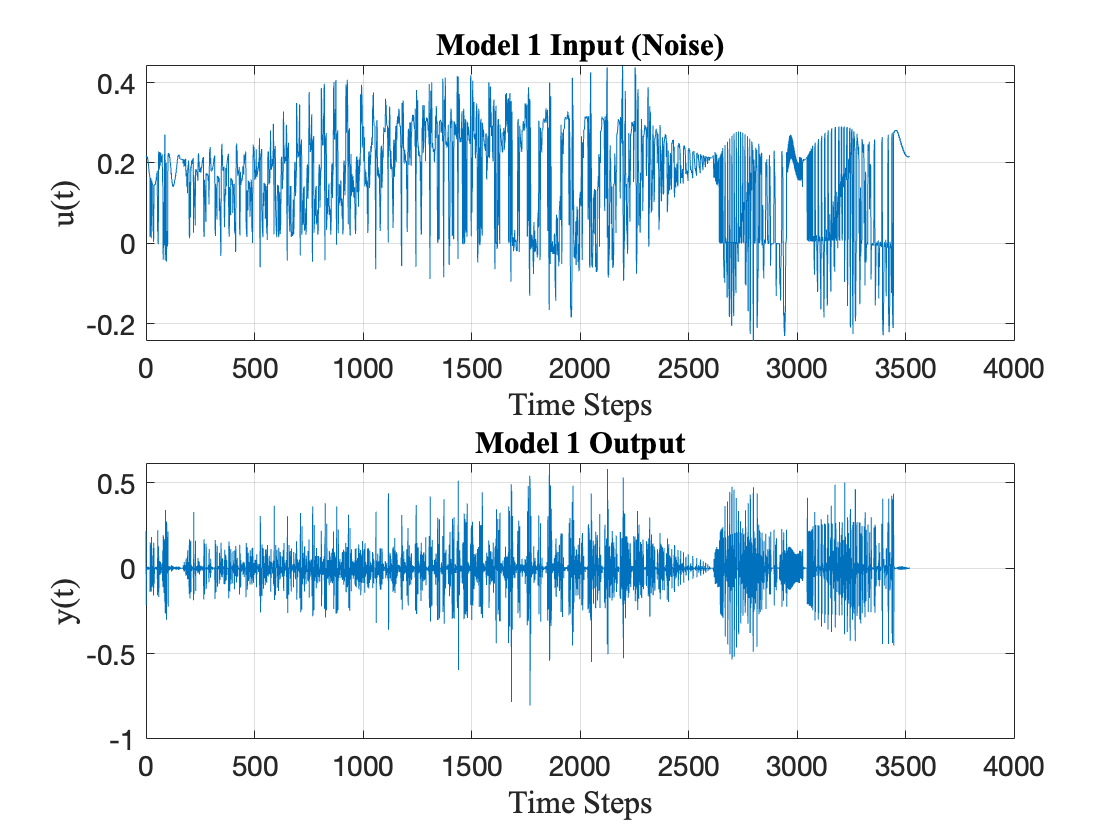

figure(1);subplot(2,1,1);plot(time,utrue);title('Model 1 Input (Noise)','fontsize',16,'fontname','times');set(gca,'fontsize',14,'LineWidth',0.5);
ylabel('u(t)','fontsize',16,'fontname','times');xlabel('Time Steps','fontsize',16,'fontname','times');grid;%axis([0, 100, -10, 10]);
subplot(2,1,2);plot(time,ytrue);title('Model 1 Output','fontsize',16,'fontname','times');set(gca,'fontsize',14,'LineWidth',0.5);
ylabel('y(t)','fontsize',16,'fontname','times');xlabel('Time Steps','fontsize',16,'fontname','times');grid;%axis([0, 100, -10, 10]);

Build up the Autoregressive model

ans = 0

MSE = 0.47859, with nstar= 1


ans = 0

MSE = 0.23823, with nstar= 2


ans = 0

MSE = 0.2385, with nstar= 3


ans = 0

MSE = 0.23436, with nstar= 4


ans = 0

MSE = 0.23452, with nstar= 5


ans = 0

MSE = 0.23446, with nstar= 6


ans = 0

MSE = 0.23379, with nstar= 7


ans = 0

MSE = 0.23423, with nstar= 8


ans = 0

MSE = 0.23309, with nstar= 9


ans = 0

MSE = 0.23362, with nstar= 10


ans = 0

MSE = 0.23612, with nstar= 11


ans = 0

MSE = 0.23737, with nstar= 12


ans = 0

MSE = 0.23952, with nstar= 13


ans = 0

MSE = 0.24224, with nstar= 14


ans = 0

MSE = 0.24392, with nstar= 15


ans = 0

MSE = 0.24664, with nstar= 16


ans = 0

MSE = 0.24943, with nstar= 17


ans = 0

MSE = 0.25241, with nstar= 18


ans = 0

MSE = 0.2554, with nstar= 19


ans = 0

MSE = 0.25829, with nstar= 20


ans = 0

MSE = 0.26121, with nstar= 21


ans = 0

MSE = 0.26429, with nstar= 22


ans = 0

MSE = 0.26751, with nstar= 23


ans = 0

MSE = 0.27097, with nstar= 24


ans = 0

MSE = 0.27447, with nstar= 25


ans = 0

MSE = 0.27811, with nstar= 26


ans = 0

MSE = 0.28184, with nstar= 27


ans = 0

MSE = 0.28555, with nstar= 28


ans = 0

MSE = 0.28945, with nstar= 29


ans = 0

MSE = 0.29352, with nstar= 30


ans = 0

MSE = 0.29749, with nstar= 31


ans = 0

MSE = 0.3018, with nstar= 32


ans = 0

MSE = 0.30621, with nstar= 33


ans = 0

MSE = 0.31072, with nstar= 34


ans = 0

MSE = 0.31484, with nstar= 35


ans = 0

MSE = 0.31906, with nstar= 36


ans = 0

MSE = 0.32399, with nstar= 37


ans = 0

MSE = 0.32888, with nstar= 38


ans = 0

MSE = 0.33401, with nstar= 39


ans = 0

MSE = 0.33921, with nstar= 40


ans = 0

MSE = 0.34463, with nstar= 41


ans = 0

MSE = 0.35047, with nstar= 42


ans = 0

MSE = 0.35634, with nstar= 43


ans = 0

MSE = 0.36185, with nstar= 44


ans = 0

MSE = 0.36683, with nstar= 45


ans = 0

MSE = 0.37206, with nstar= 46


ans = 0

MSE = 0.3789, with nstar= 47


ans = 0

MSE = 0.38593, with nstar= 48


ans = 0

MSE = 0.39279, with nstar= 49


ans = 0

MSE = 0.40041, with nstar= 50


ans = 0

MSE = 0.40838, with nstar= 51


ans = 0

MSE = 0.41593, with nstar= 52


ans = 0

MSE = 0.42373, with nstar= 53


ans = 0

MSE = 0.43247, with nstar= 54


ans = 0

MSE = 0.44183, with nstar= 55


ans = 0

MSE = 0.45095, with nstar= 56


ans = 0

MSE = 0.46117, with nstar= 57


ans = 0

MSE = 0.47168, with nstar= 58


ans = 0

MSE = 0.4821, with nstar= 59


ans = 0

MSE = 0.49367, with nstar= 60


ans = 0

MSE = 0.50504, with nstar= 61


ans = 0

MSE = 0.51798, with nstar= 62


ans = 0

MSE = 0.53161, with nstar= 63


ans = 0

MSE = 0.54597, with nstar= 64


ans = 0

MSE = 0.56112, with nstar= 65


ans = 0

MSE = 0.57715, with nstar= 66


ans = 0

MSE = 0.59412, with nstar= 67


ans = 0

MSE = 0.61188, with nstar= 68


ans = 0

MSE = 0.63084, with nstar= 69


ans = 0

MSE = 0.6507, with nstar= 70


ans = 0

MSE = 0.67232, with nstar= 71


ans = 0

MSE = 0.69539, with nstar= 72


ans = 0

MSE = 0.71984, with nstar= 73


ans = 0

MSE = 0.74643, with nstar= 74


ans = 0

MSE = 0.77478, with nstar= 75


ans = 0

MSE = 0.80551, with nstar= 76


ans = 0

MSE = 0.83907, with nstar= 77


ans = 0

MSE = 0.87541, with nstar= 78


ans = 0

MSE = 0.91468, with nstar= 79


ans = 0

MSE = 0.95814, with nstar= 80


ans = 0

MSE = 1.0055, with nstar= 81


ans = 0

MSE = 1.0582, with nstar= 82


ans = 0

MSE = 1.1169, with nstar= 83


ans = 0

MSE = 1.1815, with nstar= 84


ans = 0

MSE = 1.2553, with nstar= 85


ans = 0

MSE = 1.3366, with nstar= 86


ans = 0

MSE = 1.4321, with nstar= 87


ans = 0

MSE = 1.5413, with nstar= 88


ans = 0

MSE = 1.6696, with nstar= 89


ans = 0

MSE = 1.82, with nstar= 90


ans = 0

MSE = 2.0019, with nstar= 91


ans = 0

MSE = 2.2234, with nstar= 92


ans = 0

MSE = 2.5013, with nstar= 93


ans = 0

MSE = 2.8586, with nstar= 94


ans = 0

MSE = 3.3348, with nstar= 95


ans = 0

MSE = 4.0012, with nstar= 96


ans = 0

MSE = 5.0006, with nstar= 97


ans = 0

MSE = 6.6666, with nstar= 98


ans = 0

MSE = 9.9894, with nstar= 99


ans = 0

MSE = 19.9247, with nstar= 100


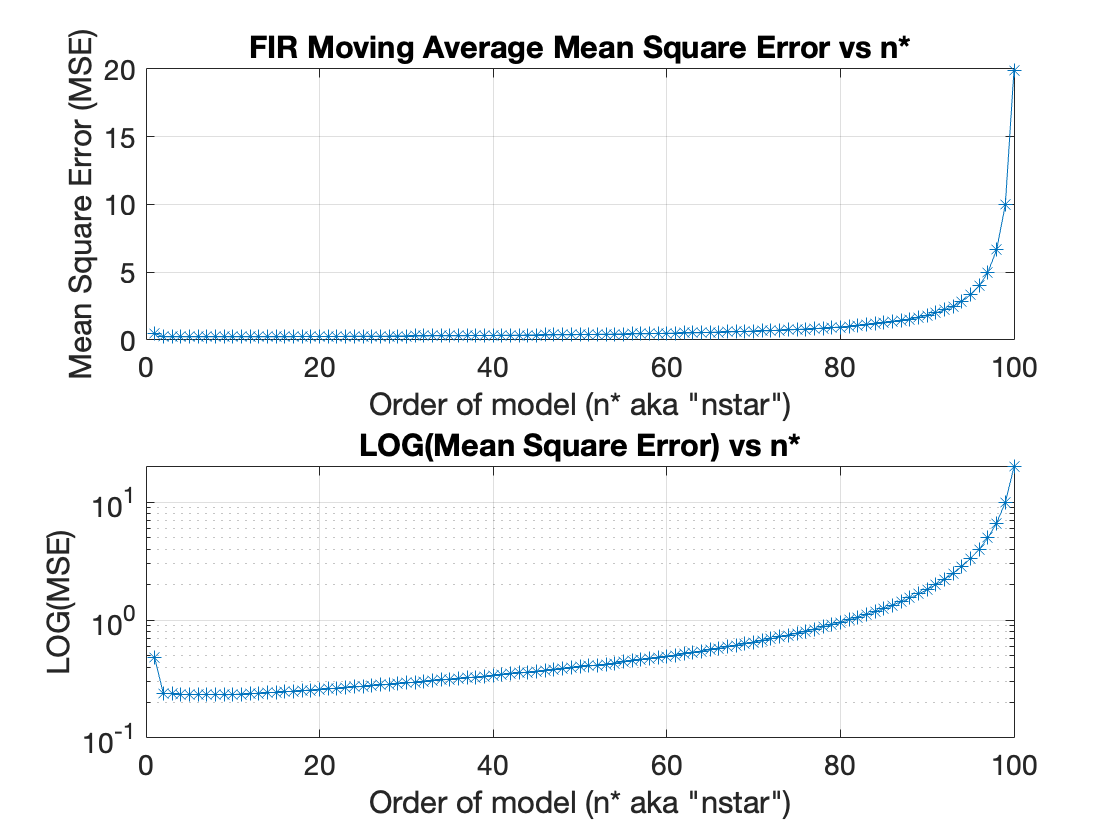

clear y1 u1 n m;  
n0=0;nEnd=10;  m0=1;mEnd=10; % Outer Loop for n & Inner loop for m (Set n0=0 for FIR, set n>0 for Transfer Function)
if n0 > 0       %Execute this loop for Transfer Function model (AUTOREGRESSIVE Moving Average)
    for n = n0:nEnd;    %Outer Loop for number of Autogressive outputs to include
        for m = 1:n     %Inner Loop for number of Moving Average inputs to include
            PHI=[]; nstar=n+m;      % Initialize PHI & nstar
            for tt = 1:ndata % Innermost loop for number of time samples
                theta=[zeros(nstar,1)];       % Initialize [Theta]
                y1=[zeros(n,1);ytrue]; u1=[zeros(m,1);utrue]; %Delay input & output vectors
                PHI(tt,:)=[flipud(y1(tt:tt+n-1,1))' flipud(u1(tt:tt+m-1,1))']; %Form [PHI]
            end             % end of Innermost loop for number of time samples
            thetahat=pinv(PHI'*PHI)*PHI'*ytrue; %Calculate estimate using Batch Least Squares
            yhat=PHI*thetahat;      % Calculate estimated output using theta hat
            mse(m,n)=(ytrue-yhat).^2%sum((ytrue-yhat)'*(ytrue-yhat))/(101-(n+m));   %Mean Square Error
        end                 % end of Inner Loop for number of Moving Average inputs to include
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%                       Plot Mean Square Error vs. nstar                       %%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        figure(2);subplot(2,1,1);plot(n+1:nstar,mse(1:nstar-n,n),'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
        set(gca,'fontsize',14,'LineWidth',0.5);axis([0,20,0,0.00025]);
        text(4,1.7e-4,'n=1 (only 1 output) not depicted.  MSE(n=1)~0.05','fontsize',14)
        title('Mean Square Error vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');
        
        figure(2);subplot(2,1,2);semilogy(n+1:nstar,mse(1:nstar-n,n),'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
        set(gca,'fontsize',14,'LineWidth',0.5);
        title('LOG(Mean Square Error) vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');        
        
    end             % End Outer Loop for number of Autogressive outputs to include
    hold off;grid;        %Stop adding lines to MSE plot

    else    %Execute this loop for FIR/Transverse model (NON-AUTOREGRESSIVE Moving Average)
    for m = m0:mEnd,
        PHI=[];                         % Defines empty regression matrix (PHI)
        for tt = 1:ndata
            % size parameter vector: 
            % theta=[a1; a2; ...an; b1; b2; ...bm]
            theta=[zeros(m,1)];             % Defines parameter vector(theta)of zeros
            % size the regression vector:
            % phi(t-1)=[-y(t-1), -y(t-2),..., -y(t-n), u(t+m-n), u(t+m-n-2,...,u(t-n)]
            u1=[zeros(m,1);utrue];        %augments input vector with delay (m)
            PHI(tt,:)=flipud(u1(tt:tt+m-1,1))';
            %PHI=[PHI; phiT];
        end          % end of data loop
        thetahat=inv(PHI'*PHI)*PHI'*ytrue;0
        yhat=PHI*thetahat;
        err=ytrue-yhat;
        mse(m,1)=sum(err'*err)/(101-m);
        disp(['MSE = ',num2str(mse(m,1)),', with nstar= ',num2str(m)])
        
    end
    
      figure(2);subplot(2,1,1);    plot((m0:mEnd),mse,'-*'); set(gca,'fontsize',14,'LineWidth',0.5);grid;
    title('FIR Moving Average Mean Square Error vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');
    
    figure(2);subplot(2,1,2);semilogy((m0:mEnd),mse,'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
    set(gca,'fontsize',14,'LineWidth',0.5);grid;
    title('LOG(Mean Square Error) vs n*');ylabel('LOG(MSE)');xlabel('Order of model (n* aka "nstar")');        
end         % end of if-else loop  

Save the data for contour plot

X2 = [X(:,1),X(:,2)];
[xx1,yy1,zz1]=griddata(X2(:,1),X2(:,2),yhat,linspace(0,10,100),linspace(0,10,100)','v4');
[xx2,yy2,zz2]=griddata(X2(:,1),X2(:,2),ytrue,linspace(0,10,100),linspace(0,10,100)','v4');
[xx3,yy3,zz3]=griddata(X2(:,1),X2(:,2),utrue,linspace(0,10,100),linspace(0,10,100)','v4');
[xxbench,yybench,zzbench]=griddata(X2(:,1),X2(:,2),vv(:,50),linspace(0,10,100),linspace(0,10,100)','v4');

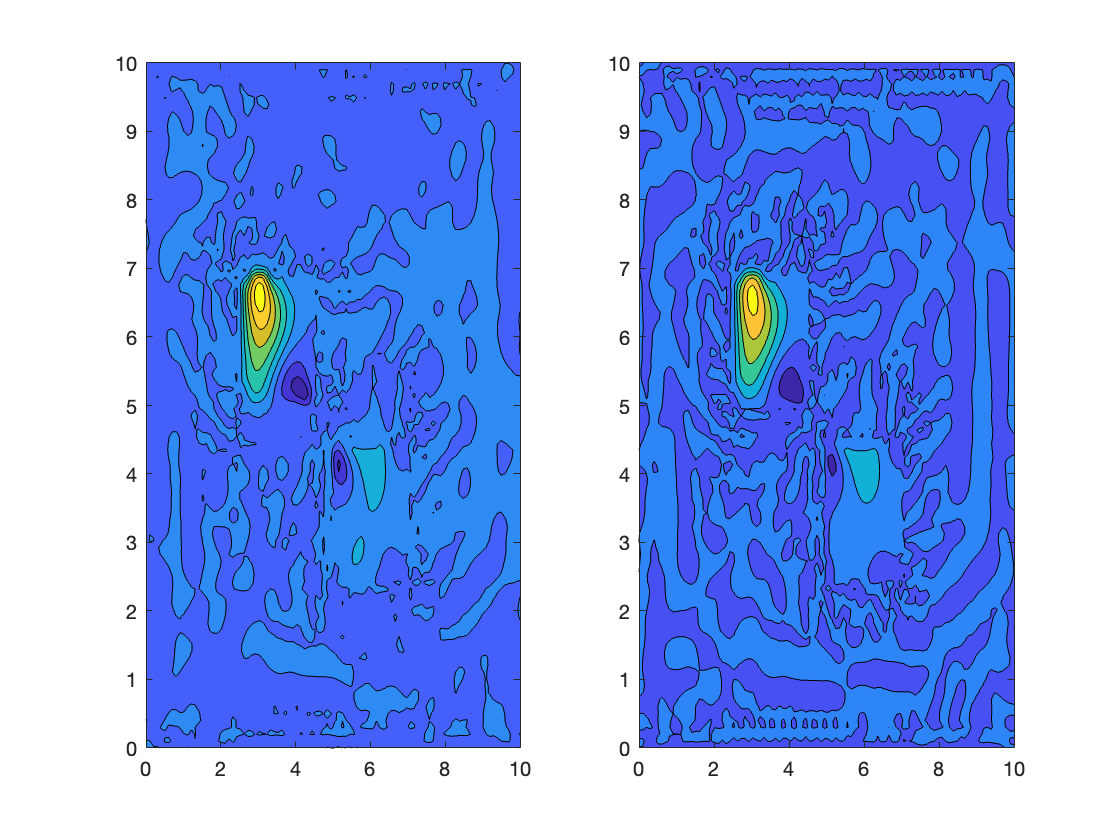

subplot(1,2,1)
contourf(xx1,yy1,zz1);
subplot(1,2,2)
contourf(xx2,yy2,zz2);

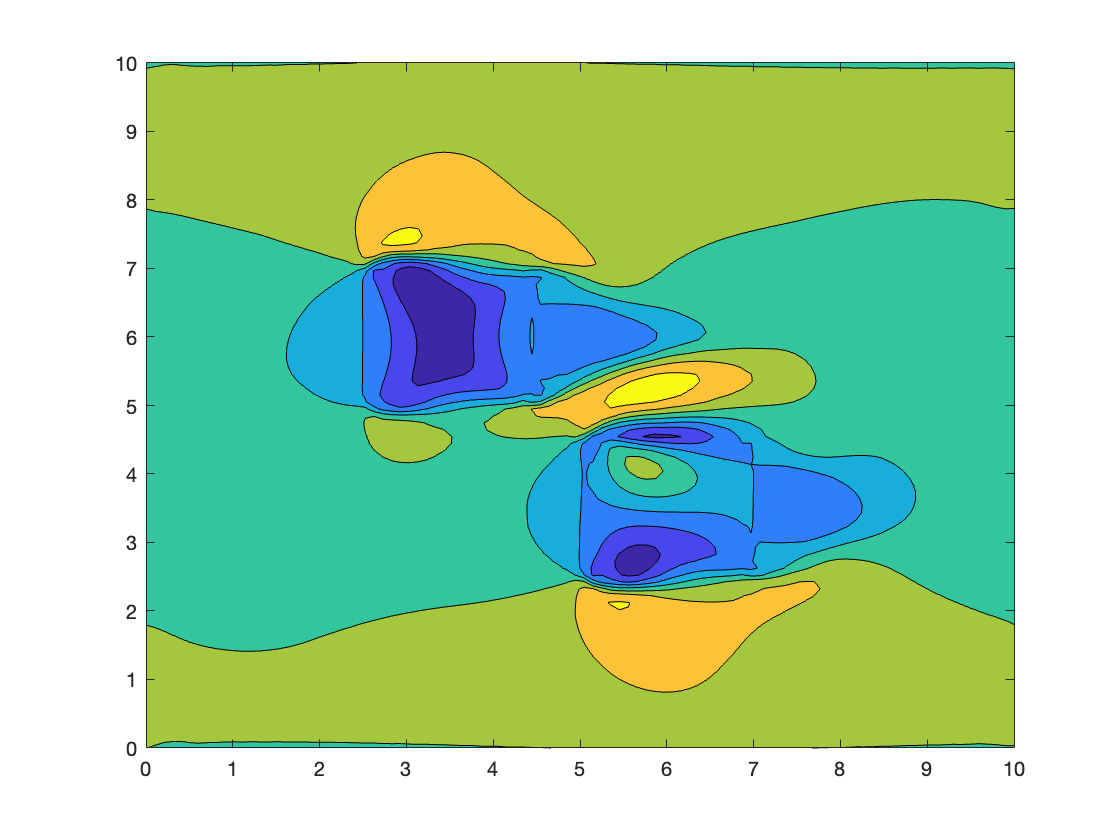

figure()
contourf(xx3,yy3,zz3);

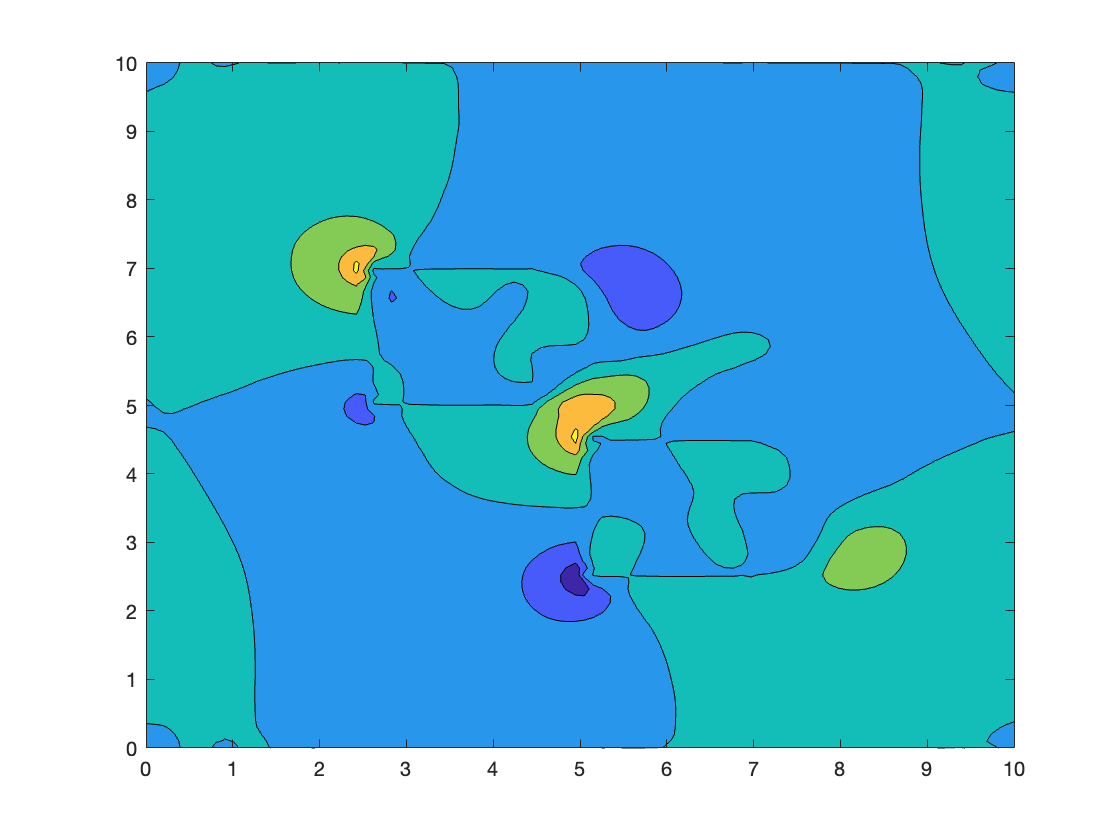

figure
contourf(xxbench,yybench,zzbench);